clear all;
dataset = load("../data/dataset.mat");
addpath("../object_simulation/");
addpath("../linear_model/");
addpath("../nets/");
u_train = dataset.u_train;
y_train = dataset.y_train;
u_val = dataset.u_val;
y_val = dataset.y_val;

tau = 3;
nb = 4;
na = 2;

run("../nets/chosen_oe_model_oe_training_bfgs/model.m");

sigma_u = 0.001; sigma_y = 0.001;
kstart = 10; kend = 1000;

N = 10; Nu = 5; lambda = 0.8;

y_set(1:kstart) = 0;
y_set(kstart+1:260) = 0.6;
y_set(261:510) = 0;
y_set(511:760) = -1.7;
y_set(761:kend) = -0.5;

min_u = -1; max_u = 1;
max_du = 1;

delta_u_max_vec = [2 0.05 0.1 0.2 0.5]; E = [];
figure;
% stairs(y_set);
hold on

for max_du = delta_u_max_vec
   
u(1:kend) = 0;
y_obj(1:kend) = 0;
x1km1=0; x2km1=0;

for k = kstart:kend
        % Predykcja wyjścia modelu na horyzoncie N
        du = zeros(Nu, 1); % Zmiana sterowania na horyzoncie sterowania
        
        % Optymalizacja zmiennych sterujących
        options = optimset('Display', 'off');
        du_opt = fmincon(@(du) cost_function(du, N, Nu, lambda, y_set, k, y_obj, u, tau, nb, w20, w2, w10, w1), ...
                         du, [], [], [], [], -max_du * ones(Nu, 1), max_du * ones(Nu, 1), @(du) control_constraints(du, u, k, min_u, max_u), options);

        % Aktualizacja sterowania
        u(k) = u(k-1) + du_opt(1);

        % Symulacja obiektu
        [y_obj(k), x1km1, x2km1] = simulation_object(x1km1, x2km1, u(k-tau));

        % Obliczanie wyjścia modelu
        y_model(k) = y_nn_model(y_obj(k-1), y_obj(k-2), u(k-tau), u(k-nb), w20, w2, w10, w1);
end

% stairs(y_obj);
stairs(u);
e = sum((y_set - y_obj).^2);
E = [E e];
end

disp(E);

   44.8487   74.6884   59.7622   51.5546   46.3960



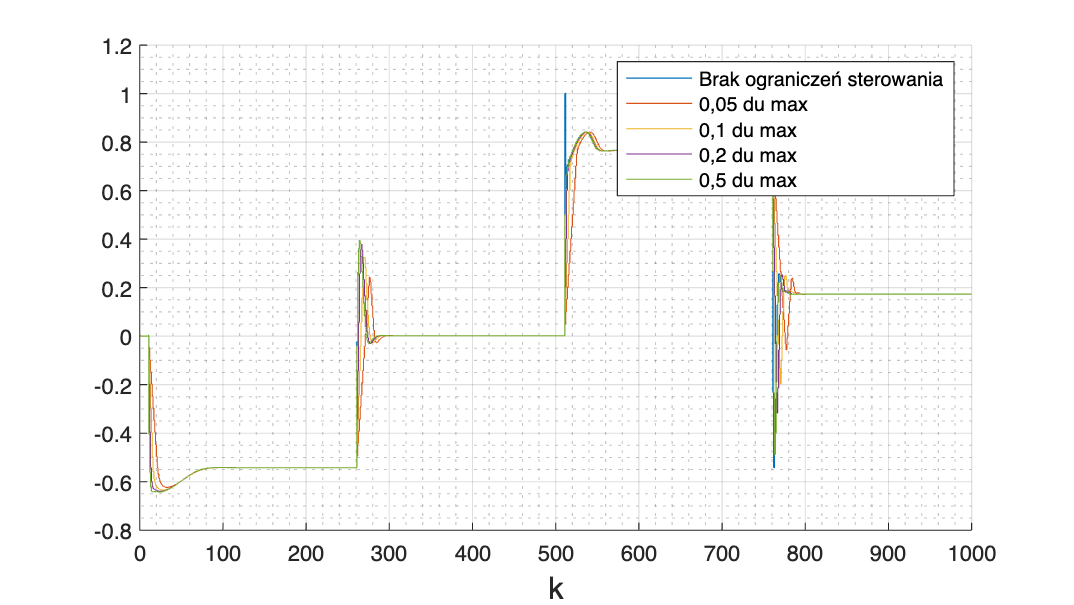


grid on;
grid(gca, 'minor');
xlabel('k', 'fontsize', 14);
% legend('Wartosc zadana', 'Brak ograniczeń sterowania', '0,05 du max', '0,1 du max', '0,2 du max', '0,5 du max');
legend('Brak ograniczeń sterowania', '0,05 du max', '0,1 du max', '0,2 du max', '0,5 du max');
x0 = 10;
y0 = 10;
width = 1280;
height = 720;
set(gcf, 'position', [x0, y0, width, height]);

% exportgraphics(gcf, "../images/zad_dod_no_delta_u_max_u.pdf", 'ContentType', 'vector');

function J = cost_function(du, N, Nu, lambda, y_set, k, y_obj, u, tau, nb, w20, w2, w10, w1)
    % Funkcja kosztu
    J = 0;
    u_temp = u;
    y_temp = y_obj;

    for i = 1:N
        % Aktualizacja sterowania
        if i <= Nu
            u_temp(k + i - 1) = u_temp(k + i - 2) + du(i);
        else
            u_temp(k + i - 1) = u_temp(k + i - 2);
        end

        % Predykcja wyjścia modelu
        y_pred = y_nn_model(y_temp(k + i - 1 - 1), y_temp(k + i - 1 - 2), u_temp(k + i - 1 - tau), u_temp(k + i - 1 - nb), w20, w2, w10, w1);
        y_temp(k + i - 1) = y_pred;

        % Obliczenie funkcji kosztu
        J = J + (y_set(k) - y_pred)^2;
    end

    % Karanie zmian sterowania
    J = J + lambda * sum(du.^2);
end

function [c, ceq] = control_constraints(du, u, k, min_u, max_u)

    u_temp = u(k) + cumsum(du);
    c = [u_temp - max_u; min_u - u_temp];
    ceq = [];
end

